%Import 'exoplanets.txt'
table = readtable("exoplanets.txt")

table = 2637×9 table
             Name               Mass     Radius    Orbit    Smass    Distance    Habitable          Method           Year
    _______________________    ______    ______    _____    _____    ________    _________    ___________________    ____

    {'1RXS 1609 b'        }    4451.2    19.04      330     0.73        145          0        {'imaging'        }    2008
    {'1SWASP J1407 b'     }    6358.8    10.94      3.9      0.9        133          0        {'primary transit'}    2012
    {'2M 0103-55(AB) b'   }    4133.2     11.4       84      0.4       47.2          0        {'imaging'        }    2013
    {'2M 0122-24 b'       }    6358.8     11.2       52      0


%a
habit = find(table.Habitable==1);
close = min(table.Distance);
name = table.Name(habit);

name = 54×1 cell array
    {'GJ 163 c'    }
    {'GJ 180 b'    }
    {'GJ 180 c'    }
    {'GJ 273 b'    }
    {'GJ 422 b'    }
    {'GJ 667 C c'  }
    {'GJ 667 C e'  }
    {'GJ 667 C f'  }
    {'GJ 682 c'    }
    {'GJ 832 c'    }
    {'GJ 3293 d'   }
    {'GJ 3323 b'   }
    {'HD 40307 g'  }
    {'HD 283869 b' }
    {'K2-3 d'      }
    {'K2-9 b'      }
    {'K2-18 b'     }
    {'K2-72 e'     }
    {'Kapteyn b'   }
    {'Kepler-22 b' }
    {'Kepler-61 b' }
    {'Kepler-62 e' }
    {'Kepler-62 f' }
    {'Kepler-174 d'}
    {'Kepler-186 f'}
    {'Kepler-283 c'}
    {'Kepler-296 e'}
    {'Kepler-296 f'}
    {'Kepler-298 d'}
    {'Kepler-438 b'}



%b
habitable = length(habit);
disp(habitable)

    54



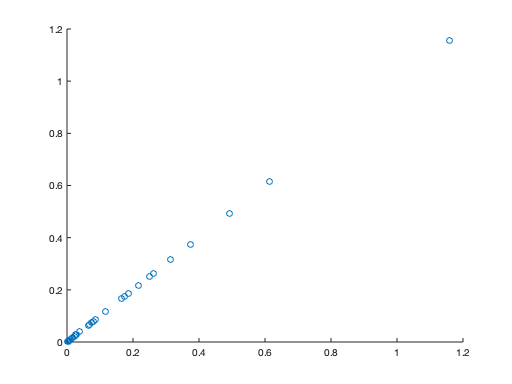

scatterplot =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×54 double]
              YData: [1×54 double]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


m = table.Mass(habit);
r = table.Radius(habit);
a= table.Orbit(habit);
x = planet(m,r,a);
y = planet(m,r,a); 
scatterplot = scatter(x,y)


%c

